folderPath =  'C:\Users\Henry\Nutstore\1\Nature_Pinwheel\Figs\Fig2\data\Varing_conn_radius\Processed_SigEE_SigEI_data';
matFiles = dir(fullfile(folderPath, '*.mat'));

for k = 1:length(matFiles)
    % Full path to the .mat file
    matFilePath = fullfile(folderPath, matFiles(k).name);

    % Load the .mat file
    load(matFilePath);

    % Display the file name
    disp(['Processed file: ', matFiles(k).name]);
end

Processed file: Processed_SigEE0.8SigEI1.3.mat
Processed file: Processed_SigEE1.1SigEI1.5.mat
Processed file: Processed_SigEE1.4SigEI1.7.mat
Processed file: Processed_SigEE1.7SigEI1.9.mat
Processed file: Processed_SigEE2.0SigEI2.0.mat
Processed file: Processed_SigEE2.3SigEI2.2.mat
Processed file: Processed_SigEE2.6SigEI2.4.mat
Processed file: Processed_SigEE2.9SigEI2.6.mat
Processed file: Processed_SigEE3.2SigEI2.7.mat
Processed file: Processed_SigEE3.5SigEI2.9.mat


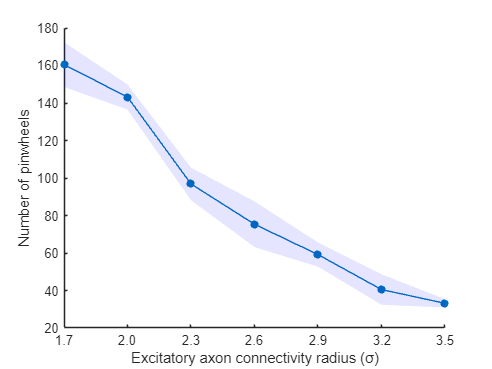



% Example 3x6 matrix
data = [Pw_SigEE1p7SigEI1p9_data(1:6,1), Pw_SigEE2p0SigEI2p0_data(1:6,1), Pw_SigEE2p3SigEI2p2_data(1:6,1),...
        Pw_SigEE2p6SigEI2p4_data(1:6,1), Pw_SigEE2p9SigEI2p6_data(:,1), Pw_SigEE3p2SigEI2p7_data(:,1),...
        Pw_SigEE3p5SigEI2p9_data(1:6,1)];

% Calculate the mean and standard deviation for each column
means = mean(data);
std_devs = std(data);

% Create a scatter plot
figure;
% subplot(2,2,1);
% scatter(1:7, means, 'filled');
hold on;
scatter(1:7, means, 'filled');
plot(means, 'Color', "#0072BD","LineWidth",1);


% Shading for standard deviation
x = 1:7;
x_rev = x(end:-1:1);
y_upper = means + std_devs;
y_lower = means - std_devs;
y_lower = y_lower(end:-1:1);

fill([x, x_rev], [y_upper, y_lower], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

% Add error bars for the standard deviation
% errorbar(1:7, means, std_devs, 'LineStyle', 'none');

% Add labels if needed
% figure;
% subplot(1,4,1);
xticks(1:7);
xticklabels({'1.7', '2.0', '2.3', '2.6', '2.9', '3.2','3.5'});
xlabel('Excitatory axon connectivity radius (σ)');
ylabel('Number of pinwheels');
xlim([1,7]);
% title('Mean Values with Standard Deviation Error Bars');

hold off;

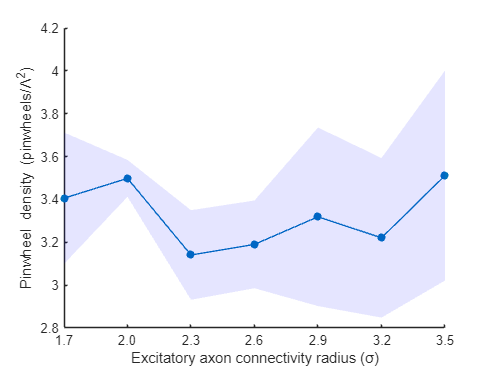

data2 = [Pw_SigEE1p7SigEI1p9_data(1:6,2), Pw_SigEE2p0SigEI2p0_data(1:6,2), Pw_SigEE2p3SigEI2p2_data(1:6,2),...
        Pw_SigEE2p6SigEI2p4_data(1:6,2), Pw_SigEE2p9SigEI2p6_data(:,2), Pw_SigEE3p2SigEI2p7_data(:,2),...
        Pw_SigEE3p5SigEI2p9_data(1:6,2)];

% Calculate the mean and standard deviation for each column
means2 = mean(data2);
std_devs2 = std(data2);

% Create a scatter plot
figure;
% subplot(2,2,2);
hold on;
scatter(1:7, means2, 'filled');
plot(means2, 'Color', "#0072BD","LineWidth",1);

% Add error bars for the standard deviation
% errorbar(1:7, means2, std_devs2, 'LineStyle', 'none');

% Shading for standard deviation
x2 = 1:7;
x_rev2 = x2(end:-1:1);
y_upper2 = means2 + std_devs2;
y_lower2 = means2 - std_devs2;
y_lower2 = y_lower2(end:-1:1);

fill([x2, x_rev2], [y_upper2, y_lower2], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

% Add labels if needed
% figure;
xticks(1:7);
xticklabels({'1.7', '2.0', '2.3', '2.6', '2.9', '3.2','3.5'});
xlabel('Excitatory axon connectivity radius (σ)');
ylabel('Pinwheel density (pinwheels/Ʌ^2)');
xlim([1,7]);
% title('Mean Values with Standard Deviation Error Bars');

hold off;

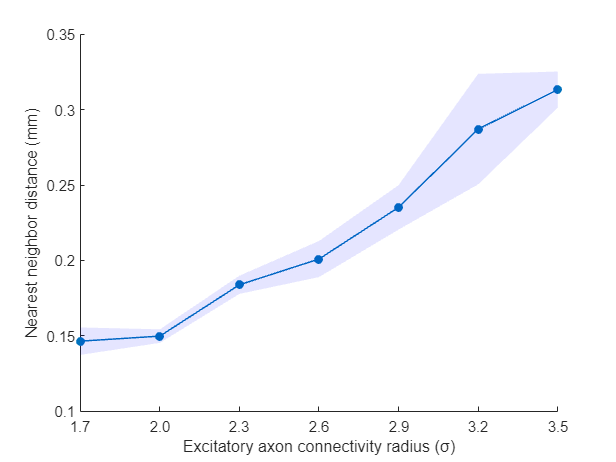

data3 = [Pw_SigEE1p7SigEI1p9_data(1:6,3), Pw_SigEE2p0SigEI2p0_data(1:6,3), Pw_SigEE2p3SigEI2p2_data(1:6,3),...
        Pw_SigEE2p6SigEI2p4_data(1:6,3), Pw_SigEE2p9SigEI2p6_data(:,3), Pw_SigEE3p2SigEI2p7_data(:,3),...
        Pw_SigEE3p5SigEI2p9_data(1:6,3)];

% Calculate the mean and standard deviation for each column
means3 = mean(data3);
std_devs3 = std(data3);

% Create a scatter plot
% figure;
figure;

hold on;
scatter(1:7, means3, 'filled');
plot(means3, 'Color', "#0072BD","LineWidth",1);

% Add error bars for the standard deviation
% errorbar(1:7, means3, std_devs3, 'LineStyle', 'none');
% Shading for standard deviation
x3 = 1:7;
x_rev3 = x3(end:-1:1);
y_upper3 = means3 + std_devs3;
y_lower3 = means3 - std_devs3;
y_lower3 = y_lower3(end:-1:1);

fill([x3, x_rev3], [y_upper3, y_lower3], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

% Add labels if needed

xticks(1:7);
xticklabels({'1.7', '2.0', '2.3', '2.6', '2.9', '3.2','3.5'});
xlabel('Excitatory axon connectivity radius (σ)');
ylabel('Nearest neighbor distance (mm)');
xlim([1,7]);
% title('Mean Values with Standard Deviation Error Bars');

hold off;

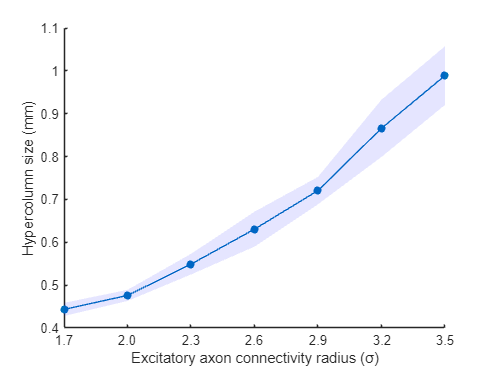

data4 = [Pw_SigEE1p7SigEI1p9_data(1:6,4), Pw_SigEE2p0SigEI2p0_data(1:6,4), Pw_SigEE2p3SigEI2p2_data(1:6,4),...
        Pw_SigEE2p6SigEI2p4_data(1:6,4), Pw_SigEE2p9SigEI2p6_data(:,4), Pw_SigEE3p2SigEI2p7_data(:,4),...
        Pw_SigEE3p5SigEI2p9_data(1:6,4)];

% Calculate the mean and standard deviation for each column
means4 = mean(data4);
std_devs4 = std(data4);

% Create a scatter plot
figure;
% subplot(2,2,4);
% scatter(1:7, means4, 'filled');
% hold on;
hold on;
scatter(1:7, means4, 'filled');
plot(means4, 'Color', "#0072BD","LineWidth", 1);


% Add error bars for the standard deviation
% errorbar(1:7, means4, std_devs4, 'LineStyle', 'none');
x4 = 1:7;
x_rev4 = x4(end:-1:1);
y_upper4 = means4 + std_devs4;
y_lower4 = means4 - std_devs4;
y_lower4 = y_lower4(end:-1:1);

fill([x4, x_rev4], [y_upper4, y_lower4], 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none');

% Add labels if needed
xticks(1:7);
xticklabels({'1.7', '2.0', '2.3', '2.6', '2.9', '3.2','3.5'});
xlabel('Excitatory axon connectivity radius (σ)');
ylabel('Hypercolumn size (mm)');
xlim([1,7]);
% title('Mean Values with Standard Deviation Error Bars');

hold off;